# Método de Newton-Raphson

syms x
%===============================
%====Definición de variables====
%===============================

%Intervalo
I = -2:0.01:1;

%Función
fx = exp(x)-x*sin(x);   %Cambiar si se quiere otra función

%x inicial
x0 = -0.5;              %Cambiar si se quiere iniciar en otro punto

%Numero de iteraciones
n = 15;                 %Cambiar para otro número de iteraciones

%Obtencion de los resultados en una tabla
tabla = f_newton_raphson(fx,x0,n)

tabla = 15×5 table
    k             xn                    f(x0)                 f´(x0)                xn+1       
    __    __________________    _____________________    ________________    __________________

     1                  -0.5        0.366817890410532    1.52474747926202    -0.740576157953756
     2    -0.740576157953756      -0.0228374626233176    1.69815678204766    -0.727127775057225
     3    -0.727127775057225    -4.60273889898466e-05      1.691249218079    -0.727100560032676
     4    -0.727100560032676    -1.95369038115728e-10    1.69123486038149    -0.727100559917157
     5    -0.727100559917157     3.62426666819231e-17    1.69123486032055    -0.727100559917157
     6    -0.727100559917157     3.62426666819231e-17    1.69123486032055    -0.727100559917157
     7    -0.727100559917157     3.6242666

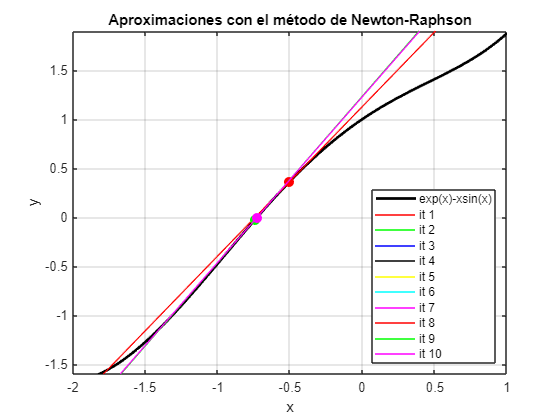


%Plot de la funcion
plot(I,subs(fx,'x',I),'LineWidth',2,'Color','k')
grid on
xlabel('x')
ylabel('y')
axis([-2 1 -1.6 1.9])
hold on

%Plot de las primeras 10 rectas
f_plot_10_rectas_tang(fx,x0,I)
hold off

legend({'exp(x)-xsin(x)', 'it 1', 'it 2', 'it 3', 'it 4', 'it 5', 'it 6', 'it 7', 'it 8', 'it 9', 'it 10'},Location='southeast')